# **Circuitos Electricos II**

**Roberto Sanchez Figueroa    **

**brrsanchezfi@unal.edu.co**

    ***Monitorias Circuitos II***

    ***Jueves, Viernes · 4:00 – 5:00pm***

    ***Información para unirse a Google Meet***

    ***Enlace a la videollamada: ***[https://meet.google.com/zit-said-kmf](https://meet.google.com/zit-said-kmf)

    ***Github:*** [https://github.com/brrsanchezfi/Circuitos_2](https://github.com/brrsanchezfi/Circuitos_2) 

# **Soluciones propuestas para los ejercicios del taller 5**

## **Problema 1, solucion analitica y grafica**

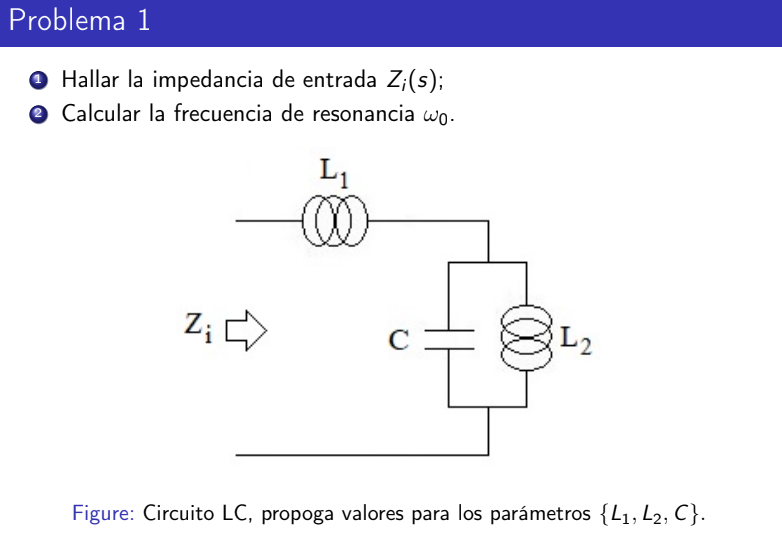

### Solucion analitica

%declaramos varibles
syms L_1 L_2 C s

%asignamos valores, uso valores grandes por conveniencia en el ejercicio 2,
%sin embargo puede usar el codigo para asignar valores cualquiera
C1 =2;
L1 =3;
L2 =5;

%escribimos la impedancia total Z_i ,la funcion paralelo suma las impedancias paralelas.

Z_i = simplify(L_1*s + paralelo((L_2*s), (1/(C*s))))

$$Z\_i = \frac{s\,\left(C\,L_{1}\,L_{2}\,s^{2}+L_{1}+L_{2}\right)}{C\,L_{2}\,s^{2}+1}$$

Recordemos que $s=\omega j$

por tanto si operamos solo la parte imaginaria podemos encontrar la frecuencias de corte y por tanto la frecuencia de resonancia. 

Apartir de la Impedancia total hallada anteriormente procedemos a despejar s, "si no queda muy claro este punto puede dirigirse al sadiku version 3 pag 630 ecuaciones 14,22 14,23 14,24 que pueden dar una idea mas clara de este punto "

%Despejamos s la impedancia total, note que para este punto omega es igual
%a s, recuerde ver la pagina del libro.
w_0 = solve(Z_i,s)

$$w\_0 = \left(\begin{array}{c} 0\\ \frac{\sqrt{-L_{1}-L_{2}}}{\sqrt{C}\,\sqrt{L_{1}}\,\sqrt{L_{2}}}\\ -\frac{\sqrt{-L_{1}-L_{2}}}{\sqrt{C}\,\sqrt{L_{1}}\,\sqrt{L_{2}}} \end{array}\right)$$


%sustituimos los valores numericos en las variables simbolicas
w_0 = subs(w_0,[L_1 L_2 C],[L1 L2 C1])

$$w\_0 = \left(\begin{array}{c} 0\\ \frac{\sqrt{2}\,\sqrt{3}\,\sqrt{5}\,\sqrt{8}\,\mathrm{i}}{30}\\ -\frac{\sqrt{2}\,\sqrt{3}\,\sqrt{5}\,\sqrt{8}\,\mathrm{i}}{30} \end{array}\right)$$


%note que tenemos 3 respuestas, sin embargo debemos escoger la respuesta
%coherente a la naturaleza de lo que estudiamos, por tanto escogemos la
%frecuencia \omega positiva.
w_0 = imag(double(w_0))

w_0 =          0
    0.5164
   -0.5164



W_0 = w_0(2)

W_0 = 0.5164

### Solucion grafica

por otra parte , una solucion igual de valida es el analisis grafico del diagrama de bode, sin embargo, es importante reconecer el metodo anterior.

Para este punto empezamos calculando la ecuacion de transferencia del sistema, no sin antes tener presente que dado  la simplisidad del sistema propuesto podemos indentificar un divisor de voltaje por el cual "suponemos nuesta senal de salida como el tal divisor", aclaro esto por que nunca se nos da una senal de salida.

%A continuacion procedemos a calcular la ecuacion de tranferencia del
%anterior problema.

H_s = simplify(paralelo((L_2*s),(1/(C*s))) / (paralelo((L_2*s),(1/(C*s))) + L_1*s))

$$H\_s = \frac{L_{2}}{C\,L_{1}\,L_{2}\,s^{2}+L_{1}+L_{2}}$$


%sustituimos los valores numericos en las variables simbolicas
H_s = simplify(subs(H_s, [L_1 L_2 C], [L1 L2 C1]))

$$H\_s = \frac{5}{30\,s^{2}+8}$$

T_s_2 = H_s;
%convertimos de symbolico a tf
H_s = sym2tf(H_s, 0)

H_s =
 
      5
  ----------
  30 s^2 + 8
 
Continuous-time transfer function.




%hacemos el posterior analizis grafico por dos metodos distintos


### Metodo 1 'manual grafico'

Identifical el pico de resonancia y posterior mente su frecuencia

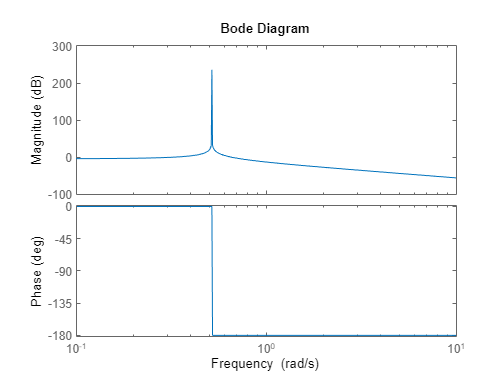

bode(H_s);

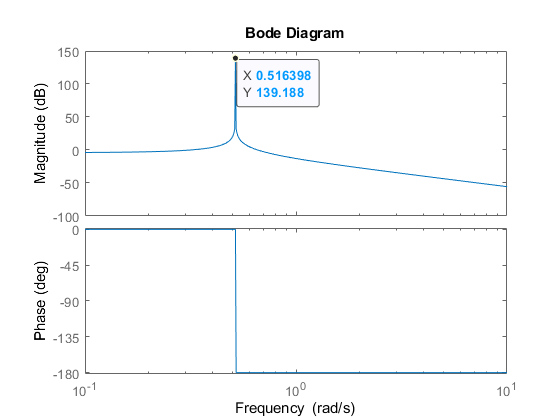

Este bode corresponde a los valores de  

C1 = 2;

L1 = 3;

L2 = 5;

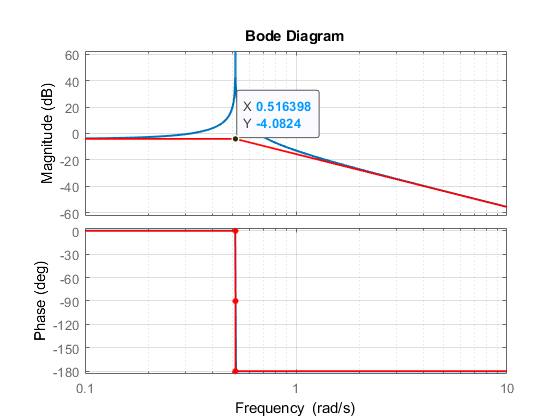

## Problema 2, Analisis 

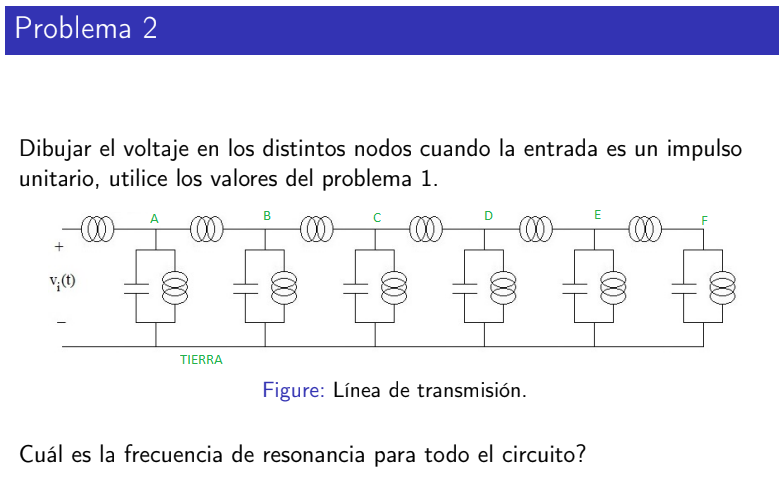

simplificar el circuito calculando el paralelo del capacitor y el inductor 2

syms C L_1 L_2 

%calculamos las impedancias nodo p
% or nodo para luego realizar los dicisores
%correspondientes a cada uno.
C_L2_p = paralelo((1/(C*s)),(L2*s));

impedancia_N_E = paralelo(C_L2_p,((L_1*s)+C_L2_p));
impedancia_N_D = paralelo(C_L2_p,((L_1*s)+impedancia_N_E));
impedancia_N_C = paralelo(C_L2_p,((L_1*s)+impedancia_N_D));
impedancia_N_B = paralelo(C_L2_p,((L_1*s)+impedancia_N_C));
impedancia_N_A = paralelo(C_L2_p,((L_1*s)+impedancia_N_B));
impedancia_total = L1*s + impedancia_N_A;
w_0 = subs(C_L2_p/impedancia_total,[L_1 L_2 C],[L1 L2 C1]);
w_0 = solve(w_0,s);
w_0 = imag(double(w_0))


w_0 =

  0×1 empty double column vector



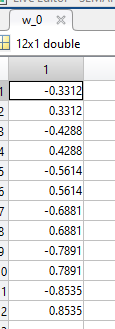

T_s = (C_L2_p/impedancia_total)  

$$T\_s = \begin{array}{l} \frac{5}{C\,\sigma_{4}\,\left(3\,s+\frac{5\,\left(L_{1}\,s+\sigma_{1}\right)}{C\,\sigma_{4}\,\left(L_{1}\,s+\frac{5}{C\,\sigma_{4}}+\sigma_{1}\right)}\right)}\\ \mathrm{where}\\ \sigma_{1}=\frac{5\,\left(L_{1}\,s+\sigma_{2}\right)}{C\,\sigma_{4}\,\left(L_{1}\,s+\frac{5}{C\,\sigma_{4}}+\sigma_{2}\right)}\\ \sigma_{2}=\frac{5\,\left(L_{1}\,s+\sigma_{3}\right)}{C\,\sigma_{4}\,\left(L_{1}\,s+\frac{5}{C\,\sigma_{4}}+\sigma_{3}\right)}\\ \sigma_{3}=\frac{5\,\left(L_{1}\,s+\frac{5\,\left(L_{1}\,s+\frac{5}{C\,\sigma_{4}}\right)}{C\,\sigma_{4}\,\left(L_{1}\,s+\frac{10}{C\,\sigma_{4}}\right)}\right)}{C\,\sigma_{4}\,\left(L_{1}\,s+\frac{5}{C\,\sigma_{4}}+\frac{5\,\left(L_{1}\,s+\frac{5}{C\,\sigma_{4}}\right)}{C\,\sigma_{4}\,\left(L_{1}\,s+\frac{10}{C\,\sigma_{4}}\right)}\right)}\\ \sigma_{4}=5\,s+\frac{1}{C\,s} \end{array}$$

T_s = subs(T_s,[L_1 L_2 C],[L1 L2 C1]);
T_s = sym2tf(T_s)

T_s =
 
          1.215e08 s^10 + 2.632e08 s^8 + 2.146e08 s^6 + 8.132e07 s^4 + 1.41e07 s^2 + 879840
  -------------------------------------------------------------------------------------------------
  7.29e08 s^12 + 1.774e09 s^10 + 1.689e09 s^8 + 7.962e08 s^6 + 1.936e08 s^4 + 2.271e07 s^2 + 994969
 
Continuous-time transfer function.



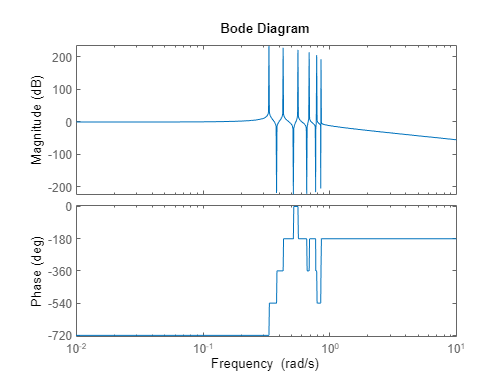

bode(T_s)

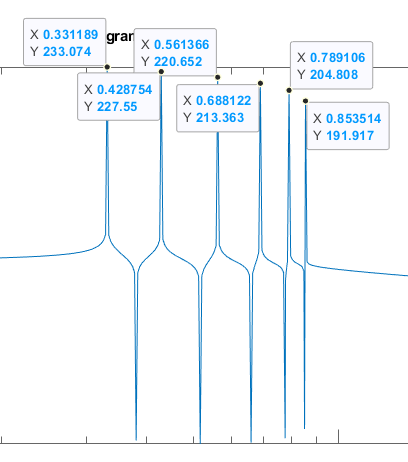

%respuesta al impulso para cada nodo

T_nodo_f =(C_L2_p/impedancia_total);
T_nodo_f = sym2tf(subs(T_nodo_f,[L_1 L_2 C],[L1 L2 C1]));%funcion de transferencia de cada nodo

T_nodo_e = (impedancia_N_E/impedancia_total);
T_nodo_e = sym2tf(subs(T_nodo_e,[L_1 L_2 C],[L1 L2 C1]));

T_nodo_d = (impedancia_N_D/impedancia_total);
T_nodo_d = sym2tf(subs(T_nodo_d,[L_1 L_2 C],[L1 L2 C1]));

T_nodo_c = (impedancia_N_C/impedancia_total);
T_nodo_c = sym2tf(subs(T_nodo_c,[L_1 L_2 C],[L1 L2 C1]));

T_nodo_b = (impedancia_N_B/impedancia_total);
T_nodo_b = sym2tf(subs(T_nodo_b,[L_1 L_2 C],[L1 L2 C1]));

T_nodo_a = (impedancia_N_A/impedancia_total);
T_nodo_a = sym2tf(subs(T_nodo_a,[L_1 L_2 C],[L1 L2 C1]));



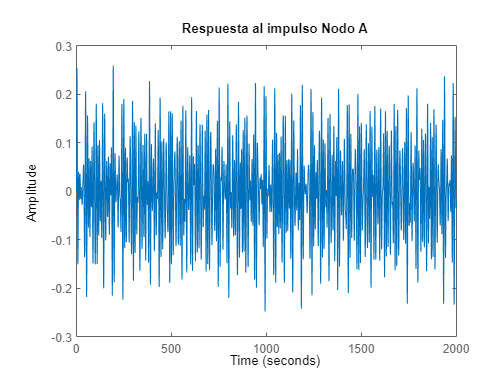

impulse(T_nodo_a)
title("Respuesta al impulso Nodo A")

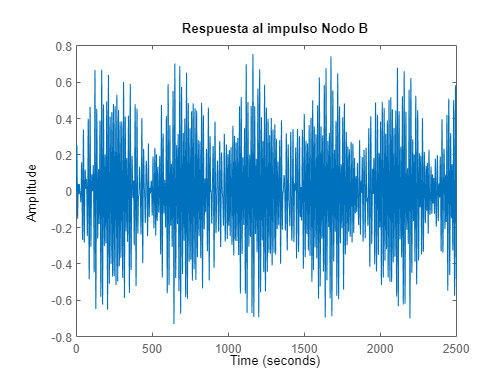

impulse(T_nodo_b)
title("Respuesta al impulso Nodo B")

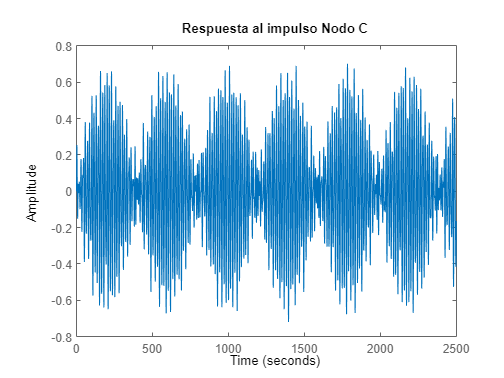

impulse(T_nodo_c)
title("Respuesta al impulso Nodo C")

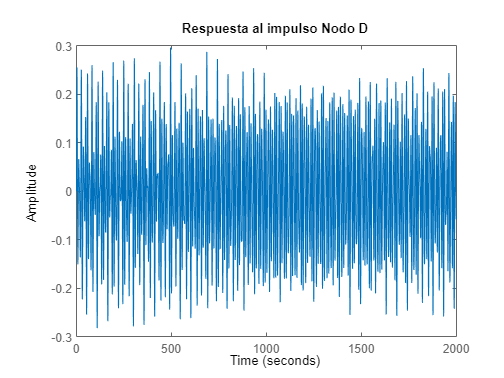

impulse(T_nodo_d)
title("Respuesta al impulso Nodo D")

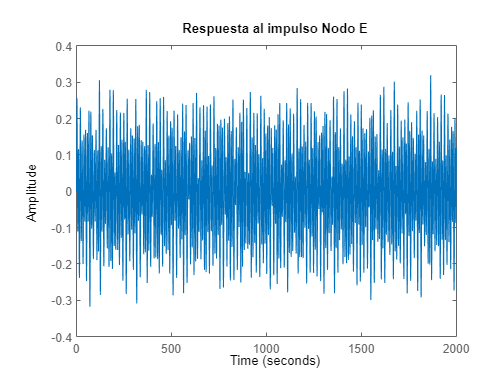

impulse(T_nodo_e)
title("Respuesta al impulso Nodo E")

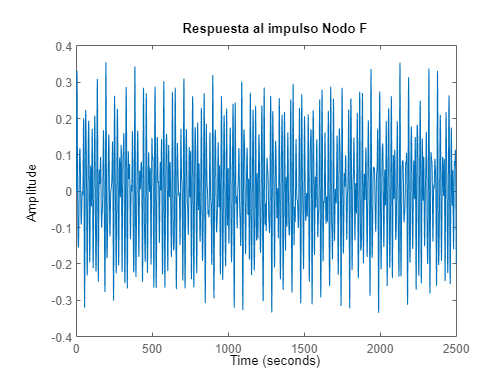

impulse(T_nodo_f)
title("Respuesta al impulso Nodo F")

## Problema 3

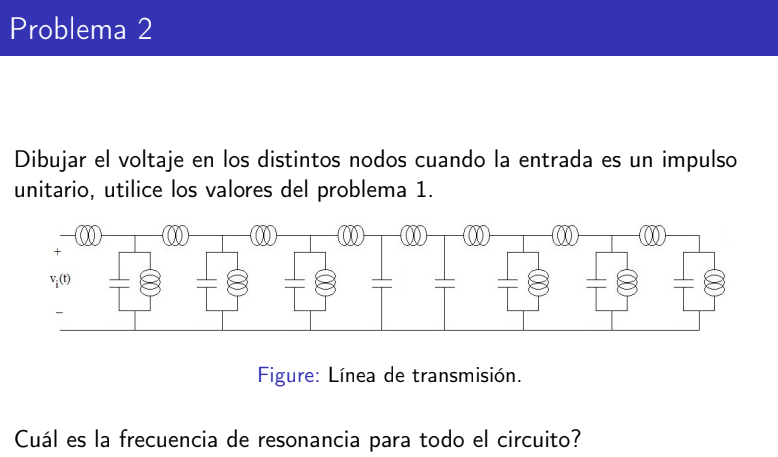

como en el anterior ejercicio simpliflico en paralelo en un equivalente

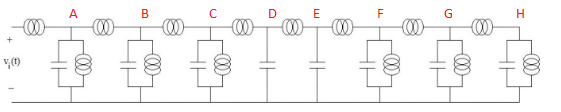

syms C L_1 L_2 s

C1 =2;
L1 =3;
L2 =5;

C_L2_p = paralelo((1/(C*s)),(L_2*s));

%IMPEDANCIA EQUIVALENTE DEL SISTEMA
impedancia_H = C_L2_p;
impedancia_N_G = paralelo(C_L2_p,((L_1*s)+C_L2_p));
impedancia_N_F = paralelo(C_L2_p,((L_1*s)+impedancia_N_G));
impedancia_N_E = paralelo((1/(C*s)),((L_1*s)+impedancia_N_F));
impedancia_N_D = paralelo((1/(C*s)),((L_1*s)+impedancia_N_E));
impedancia_N_C = paralelo(C_L2_p,((L_1*s)+impedancia_N_D));
impedancia_N_B = paralelo(C_L2_p,((L_1*s)+impedancia_N_C));
impedancia_N_A = paralelo(C_L2_p,((L_1*s)+impedancia_N_B));
impedancia_total_3 = (L_1*s)+impedancia_N_A;

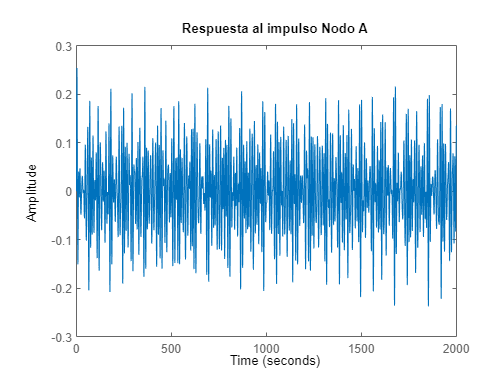


T_nodo_h = (C_L2_p/impedancia_total_3);
T_nodo_h = sym2tf(subs(T_nodo_h,[L_1 L_2 C],[L1 L2 C1]));%funcion de transferencia de cada nodo

T_nodo_g = (impedancia_N_G/impedancia_total_3);
T_nodo_g = sym2tf(subs(T_nodo_g,[L_1 L_2 C],[L1 L2 C1]));

T_nodo_f = (impedancia_N_F/impedancia_total_3);
T_nodo_f = sym2tf(subs(T_nodo_f,[L_1 L_2 C],[L1 L2 C1]));

T_nodo_e = (impedancia_N_E/impedancia_total_3);
T_nodo_e = sym2tf(subs(T_nodo_e,[L_1 L_2 C],[L1 L2 C1]));

T_nodo_d = (impedancia_N_D/impedancia_total_3);
T_nodo_d = sym2tf(subs(T_nodo_d,[L_1 L_2 C],[L1 L2 C1]));

T_nodo_c = (impedancia_N_C/impedancia_total_3);
T_nodo_c = sym2tf(subs(T_nodo_c,[L_1 L_2 C],[L1 L2 C1]));

T_nodo_b = (impedancia_N_B/impedancia_total_3);
T_nodo_b = sym2tf(subs(T_nodo_b,[L_1 L_2 C],[L1 L2 C1]));

T_nodo_a = (impedancia_N_A/impedancia_total_3);
T_nodo_a = sym2tf(subs(T_nodo_a,[L_1 L_2 C],[L1 L2 C1]));

impulse(T_nodo_a)
title("Respuesta al impulso Nodo A")

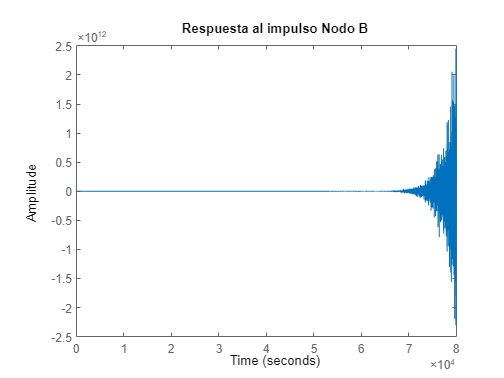

impulse(T_nodo_b)
title("Respuesta al impulso Nodo B")

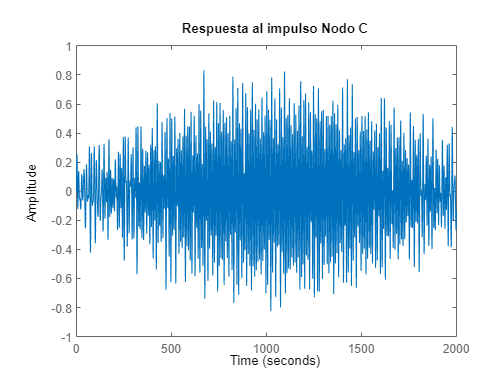

impulse(T_nodo_c)
title("Respuesta al impulso Nodo C")

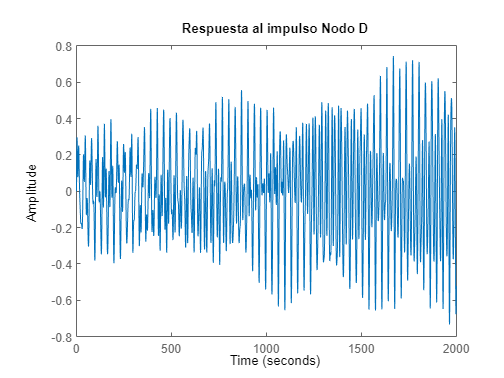

impulse(T_nodo_d)
title("Respuesta al impulso Nodo D")

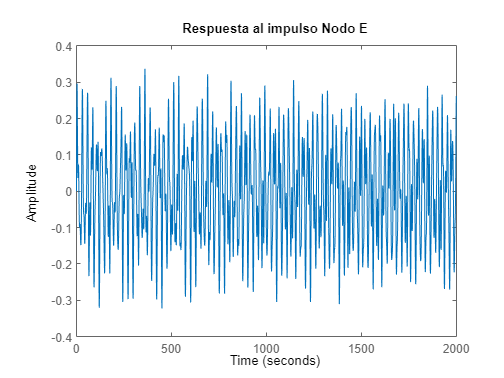

impulse(T_nodo_e)
title("Respuesta al impulso Nodo E")

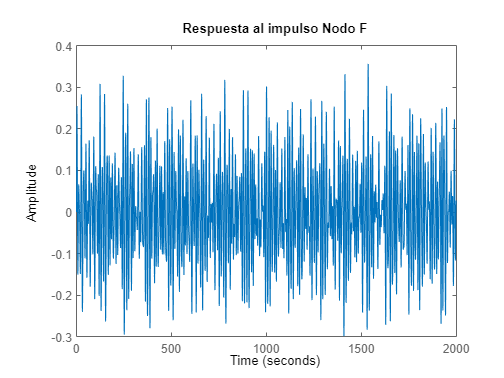

impulse(T_nodo_f)
title("Respuesta al impulso Nodo F")

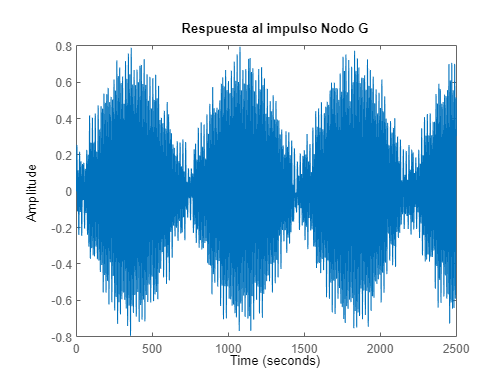

impulse(T_nodo_g)
title("Respuesta al impulso Nodo G")

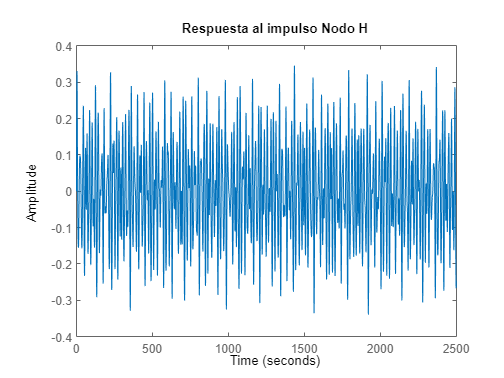

impulse(T_nodo_h)
title("Respuesta al impulso Nodo H")


T_s = (C_L2_p/impedancia_total_3);     
T_s = subs(T_s,[L_1 L_2 C],[L1 L2 C1]);
T_s = sym2tf(T_s)

T_s =
 
                                                                                                                                  
  4.374e10 s^16 + 1.283e11 s^14 + 1.553e11 s^12 + 1.003e11 s^10 + 3.747e10 s^8 + 8.178e09 s^6 + 1.006e09 s^4 + 6.29e07 s^2        
                                                                                                                                  
                                                                                                                        + 1.502e06
                                                                                                                                  
  --------------------------------------------------------------------------------------------------------------------------------
                                                                                                                                  
  2.624e11 s^18 + 8.398e11 s^16 + 1.13e12 s^14 + 8.323e11 s^12 + 3.672e11 s

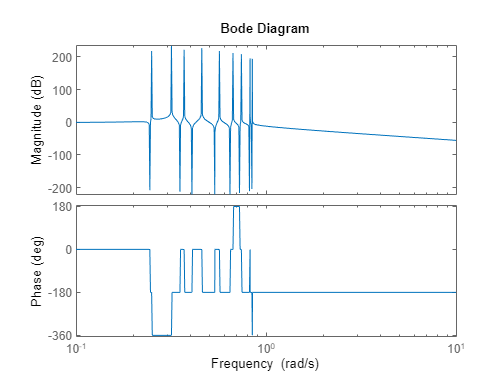

bode(T_s)

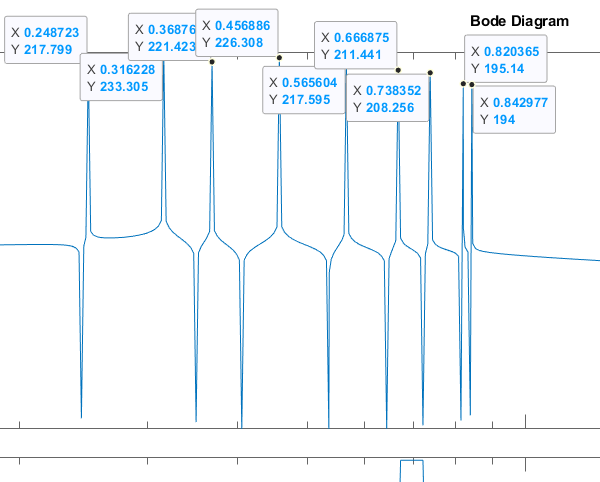

function x = paralelo(n1,n2)

    x = (n1*n2)/(n1+n2);
    

end

function t_sym = tf2sym(H) 
       [num,den] = tfdata(H);
       syms s;
       t_sym = simplify(poly2sym(cell2mat(num),s)/poly2sym(cell2mat(den),s));
end

function [ tfobj ] = sym2tf( symobj, Ts) %pasa de sym a tf    Ts es el samplin, para continuas dejar en 0
    % SYM2TF convert symbolic math rationals to transfer function
    
    if isnumeric(symobj)
        tfobj=symobj;
        return;
    end
    
    [n,d]=numden(symobj);
    num=sym2poly(n);
    den=sym2poly(d);
    
    if nargin==1
        tfobj=tf(num,den);
    else
        tfobj=tf(num,den,Ts);
    end
end
